1. Create vectors for design variables

[x1,x2] = meshgrid(0:1:300, 0:1:300);

2. Define the optimization function

f = (200.*x1)+(200.*x2)-1400;

3. Define constraints

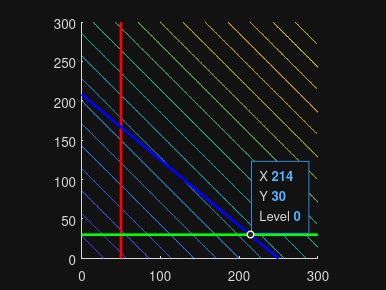

g1 = x1 - 50; % Standard form is <= 0
g2 = x2 - 30;
g3 = 20.*x1 + 24.*x2 -5000;

% plot contours of the objective
figure; hold on; axis equal;
contour(x1, x2, f, 20); % contour lines of f
colormap('parula');


contour(x1,x2,g1,[0 0],'r','LineWidth',2)
contour(x1,x2,g2,[0 0],'g','LineWidth',2)
contour(x1,x2,g3,[0 0],'b','LineWidth',2)
hold off